clear
clc

% cd frames\sick1\

% ///////////////////// INPUT \\\\\\\\\\\\\\\\\\\\\\\

prompt = 'Type in the name of the video (without the video extension): ';
folderName = input(prompt,'s');

prompt = ['Choose the segmentation algorithm:\n    ' ...
    '1) Own implementation of segmentation based on histogram binarization\n    ' ...
    '2) Segementation based on adaptive binarization\n    ' ...
    '3) Watershed segmentation with markers based on local minima/maxima\n    ' ...
    '4) Otsu Binarization\n    ' ...
    '5) Niblack Binarization\n    ' ...
    '6) Sauvola Binarization\n    ' ...
    '7) Ridler-Calvard Binarization\n    ' ...
    '8) Mean value Binarization\n    ' ...
    '9) Kapur entropy Binarization\n    ' ...
    '10) Kmeans segmentation\n    ' ...
    '11) Watershed segmentation with markers based on color using kmeans\n    ' ...
    '12) Mixed bag\n\n'];
implementation = input(prompt);

folderPath = '';
filePath = ''; 
switch implementation
    case 1
        folderPath = ['ownResults_' folderName]
        filePath = [folderPath '\ownBinarization_']
    case 2
        folderPath = ['adaptiveResults_' folderName]
        filePath = [folderPath '\adaptiveBinarization_']
    case 3
        folderPath = ['watershedResults_' folderName]
        filePath = [folderPath '\watershedSegmentation_']
    case 4
        folderPath = ['otsuResults_' folderName]
        filePath = [folderPath '\otsuBinarization_']
    case 5
        folderPath = ['niblackResults_' folderName]
        filePath = [folderPath '\niblackBinarization_']
    case 6
        folderPath = ['sauvolaResults_' folderName]
        filePath = [folderPath '\sauvolaBinarization_']
    case 7
        folderPath = ['ridlerResults_' folderName]
        filePath = [folderPath '\ridlerBinarization_']
    case 8
        folderPath = ['meanResults_' folderName]
        filePath = [folderPath '\meanBinarization_']
    case 9
        folderPath = ['kapurResults_' folderName]
        filePath = [folderPath '\kapurBinarization_']
    case 10
        folderPath = ['kmeansResults' folderName]
        filePath = [folderPath '\kmeansSegmentation_']
    case 11
        folderPath = ['watershedResults_' folderName]
        filePath = [folderPath '\watershedSegmentation_']
    otherwise
        errordlg('Choose a valid segmentation algorithm','Input Error')
        return
end

folderPath = 'watershedResults_normal'

filePath = 'watershedResults_normal\watershedSegmentation_'

frameName = '.\normal\40.jpg'

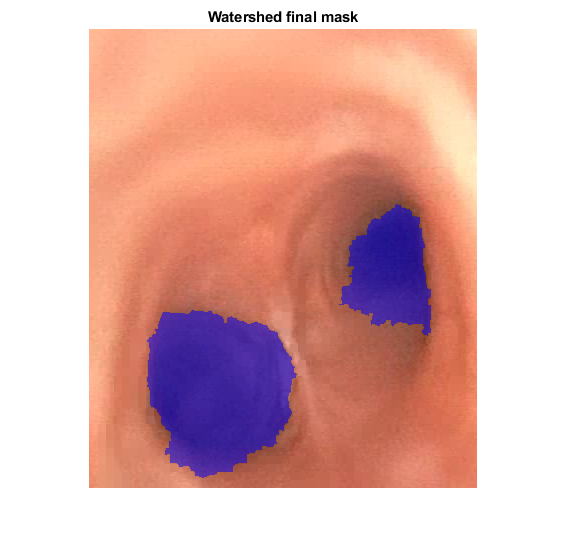


prompt = ['Choose the segmentation feature: \n    ' ...
    '1) Redness\n    ' ...
    '2) Gray level\n    ' ...
    '3) Saturation\n    ' ...
    '4) Lightness (similar to gray level, but obtaining the L value from the HSL color scheme)\n    ' ...
    '5) Green level\n    ' ...
    '6) RGB colorspace with preprocessing (for kmeans segmentation)\n    ' ...
    '7) L*a*b* colorspace with preprocessing (for kmeans segmentation)\n    ' ...
    '8) RGB without preprocessing\n\n'];
feature = input(prompt);

if exist(folderPath, 'dir')
    rmdir(folderPath,'s');
end
mkdir(folderPath);

prompt = 'Choose the number of the inital frame:';
initalFrame = input(prompt);
prompt = 'Choose the number of the final frame:';
finalFrame = input(prompt);

% Global Variables 
global S frameIx  previousThreshold previousCentroid
S = dir(fullfile(['.\' folderName '\'],'*.jpg'));
S = natsortfiles(S);

frames = {};
discardedFrames = {};

apertures = [];
aperture = -1;
areas = [];

previousThreshold = -1;
previousAperture = -1;
previousCentroid = [0 0];
minimumAperture = 7;
maximumConsecutiveMisses = 2;
consecutiveMisses = 0; % Counter of the number of consecutive misses
apertureThreshold = 0.8; % Scalar from 0 to 1

first = true;

% initializing progress bar
f = waitbar(0,'Obtaining frames...');
for frameIx = initalFrame:finalFrame
    
    frameName = fullfile(['.\' folderName],S(frameIx).name)
    frame = imread(frameName);
    
    % updating progress bar
    percentage = (frameIx - initalFrame)/(finalFrame - initalFrame);
    waitbar(percentage,f,'Processing frames...'); 
    validFrame = true;

%     figure
%     imshow(frame);
%     title('Original Frame');
    
    % //////// PREPROCESSING \\\\\\\\\\
    % ------- Image Cropping ----------
    frameCropped = imcrop(frame,[168,54,387,458]);
%     figure
%     imshow(frameCropped);
%     title('Cropped Frame');
    % ---------------------------------
    
    % Setting the centroid to the center of the image
    if first
        previousCentroid = [size(frameCropped,1)/2,size(frameCropped,2)/2];
        first = false;
    end
    
    % //////// BEST FEATURES \\\\\\\\\\
    % ---------- Channels -------------
    redChannel = frameCropped(:,:,1);
    greenChannel = frameCropped(:,:,2);
    blueChannel = frameCropped(:,:,3);
    % Create an all black channel.
%     allBlack = zeros(size(frameCropped, 1), size(frameCropped, 2), 'uint8');
    % Create a color version of the Red Channel
%     frameRed = cat(3, redChannel, allBlack, allBlack);
    % Print red channel
%     imshow(frameRed);
%     title('Red Channel only');
    % ---------------------------------
    
    % ----------- Grayness ------------
    frameGray = rgb2gray(frameCropped);
%     imshow(frameGray);
%     title('Gray scale');
    % ---------------------------------
    
    % ----------- Saturation ----------
    framehsv = rgb2hsv(frameCropped);
    frameSaturation = framehsv(:,:,2);
%     figure
%     imshow(frameSaturation)
    frameSaturation = abs(frameSaturation - 1);
    % ---------------------------------
    
    % ------------ Light --------------
    hslFrame = rgb2hsl(im2double(frameCropped));
    frameLightness = hslFrame(:,:,3);
    % ---------------------------------
    
    % \\\\\\\\\\\\\\\|/////////////////
    
    preProcessedFrame = [];
    % Filterage of frame
    switch  feature
        case 1
            preProcessedFrame = openCloseByReconstruction(redChannel);
        case 2
            preProcessedFrame = frameGray;
        case 3
            preProcessedFrame = openCloseByReconstruction(frameSaturation);
        case 4
            preProcessedFrame = openCloseByReconstruction(frameLightness);
        case 5
            preProcessedFrame = openCloseByReconstruction(greenChannel);
        case 6
            preProcessedRChannel = openCloseByReconstruction(redChannel);
            preProcessedGChannel = openCloseByReconstruction(greenChannel);
            preProcessedBChannel = openCloseByReconstruction(blueChannel);
            preProcessedFrame = cat(3,preProcessedRChannel,preProcessedGChannel,preProcessedBChannel);
        case 7
            preProcessedRChannel = openCloseByReconstruction(redChannel);
            preProcessedGChannel = openCloseByReconstruction(greenChannel);
            preProcessedBChannel = openCloseByReconstruction(blueChannel);
            preProcessedFrame = cat(3,preProcessedRChannel,preProcessedGChannel,preProcessedBChannel);
            % Change the color scheme from RGB to L*a*b* (Luminance, Green/Red tones, Blue/Yellow tones)
            preProcessedFrame = rgb2lab(preProcessedFrame);
        case 8
            preProcessedFrame = frameCropped;
    end
    
%     imshow(preProcessedFrame);
%     title('Preprocessed Frame')

    % \\\\\\\\\\\\\\\|/////////////////
    
    % ///////// BINARIZATION AND SEGMENTATION \\\\\\\\\\
        
    binFrame = [];
    switch implementation
        case 1
            try
                % Hist binaritzation
                binFrame = binBinarization(preProcessedFrame,10);
            catch
                sprintf('Error during binBinarization in frame %d',frameIx)
                validFrame = false;
            end
        case 2
            try
                % Adaptive binarization
                binFrame = imbinarize(preProcessedFrame,"adaptive", ...
                    "ForegroundPolarity","bright","Sensitivity",0.66);
                binFrame = ~binFrame;
            catch
                sprintf('Error during adaptiveBinarization in frame %d',frameIx)
                validFrame = false;
            end
        case 3
            try
                % Watershed segmentation
                binFrame = watershedSegmentation(preProcessedFrame, frameCropped);
            catch
                sprintf('Error during Watershed segmentation in frame %d',frameIx)
                validFrame = false;
            end
        case 4
            try
                % Otsu binarization
                level = graythresh(preProcessedFrame);
                binFrame = ~imbinarize(preProcessedFrame,level);
            catch
                sprintf('Error during Otsu binarization in frame %d',frameIx)
                validFrame = false;
            end
        case 5
            try
                % Niblack binarization
                binFrame = ~niblack(preProcessedFrame, ...
                    [ceil(size(preProcessedFrame,2)*0.6),ceil(size(preProcessedFrame,1)*0.6)]);
            catch
                sprintf('Error during Otsu binarization in frame %d',frameIx)
                validFrame = false;
            end
        case 6
            try
                % Sauvola binarization
                binFrame = ~sauvola(preProcessedFrame, ...
                    [ceil(size(preProcessedFrame,2)*0.6),ceil(size(preProcessedFrame,1)*0.6)]);
            catch
                sprintf('Error during Sauvola binarization in frame %d',frameIx)
                validFrame = false;
            end
        case 7
            try
                % Ridler-Calvard binarization
                level = isodata(preProcessedFrame);
                binFrame = ~imbinarize(preProcessedFrame,level);
            catch
                sprintf('Error during SauvolaRidler-Calvard binarization in frame %d',frameIx)
                validFrame = false;
            end
        case 8
            try
                % Mean value binarization
                level = mean2(preProcessedFrame);
                binFrame = preProcessedFrame <= level;
            catch
                sprintf('Error during SauvolaRidler-Calvard binarization in frame %d',frameIx)
                validFrame = false;
            end
        case 9
            try
                % Kapur entropy binarization
                binFrame = ~kapur(preProcessedFrame);
            catch
                sprintf('Error during Kapur entropy binarization in frame %d',frameIx)
                validFrame = false;
            end
        case 10 
%             try
                % kmeans segmentation
                if feature == 7
                    [~, binFrame, ~, ~] = kmeansLabSegmentation(preProcessedFrame,8,0);
                elseif feature == 6 || feature == 8
                    [binFrame, ~, ~, ~] = kmeansRGBSegmentation(preProcessedFrame,8,0); 
                end
%             catch
%                 sprintf('Error during Kmeans segementation in frame %d',frameIx)
%                 validFrame = false;
%             end
        case 11
            try
                % watershed segmentation using kmeans to extract markers
                binFrame = watershedSegmentationKmeans(preProcessedFrame);
            catch
                sprintf('Error during Kmeans segementation in frame %d',frameIx)
                validFrame = false;
            end
    end
        
%     figure
%     imshow(binFrame)

    % ---------------------------------
    % \\\\\\\\\\\\\\\|/////////////////
    
    % //////// POSTPROCESSING \\\\\\\\\\
    try
        if validFrame
            closeDiffBlobFrame = getSegment(binFrame);
        end
    catch
        sprintf('Error during funciton getSegmet of frame %d', frameIx)
        validFrame = false;
    end
%     figure
%     imshow(closeDiffBlobFrame)
    % \\\\\\\\\\\\\\\|/////////////////
    
    % Getting the area
    if validFrame
        maxDiffArea = bwarea(closeDiffBlobFrame);
    end
    
    if validFrame
        try
            aperture = getStenosisDegree(frameCropped, closeDiffBlobFrame, ['\' filePath]);
        catch
            sprintf('Error while getting the stenosis degree of frame %f', frameIx)
        end
        if previousAperture == -1 && aperture > minimumAperture
            previousAperture = aperture;
        elseif aperture < minimumAperture
            validFrame = false;
        end
    end
    % \\\\\\\\\\\\\\\|/////////////////
        
    % Adaptive result
%     secondFig = figure('visible','off');
%     segmentationOutline(frameCropped, closeAdaptiveBlobFrame);
%     title('Segmentation outline based on adaptive binarization');
%     saveas(secondFig,[pwd '\adaptiveResultsSick1\adaptiveSegmentation_' S(frameIx).name]);
    
    % Watershed result
%     thirdFig = figure('visible','off');
%     segmentationOutline(frameCropped, watershedSegmentation);
%     title('Segmentation outline based on watersheding with local minimum and maxima');
%     saveas(thirdFig,[pwd '\watershedResultsSick1\watershedSegmentation_' S(frameIx).name]);

    % ---------- Saving results -------------- %
    validAperture = false;
    if validFrame
        if aperture < previousAperture + previousAperture*apertureThreshold && ...
            aperture > previousAperture - previousAperture*apertureThreshold
        validAperture = true;
        end 
    end
    
    if (validFrame && validAperture) || (consecutiveMisses <= maximumConsecutiveMisses && aperture > minimumAperture)
        frames{end + 1} = S(frameIx).name;
        apertures = [apertures aperture];
        previousAperture = aperture;
        validFrame = true;
        consecutiveMisses = 0;
    else
        previousThreshold = - 1;
        previousAperture
        aperture
        discardedFrames{end + 1}= S(frameIx).name;
        consecutiveMisses = consecutiveMisses + 1;
    end
    % ---------------------------------------- %
end 


% closing progress bar
close(f)

% ///////////// RESULTS \\\\\\\\\\\\\\\

T = table(frames',apertures')

T = 1×2 table
       Var1        Var2 
    __________    ______

    {'40.jpg'}    148.66


% Standard Deviation of the valid apertures
variance = var(apertures)

variance = 0

standardDeviation = std(apertures)

standardDeviation = 0

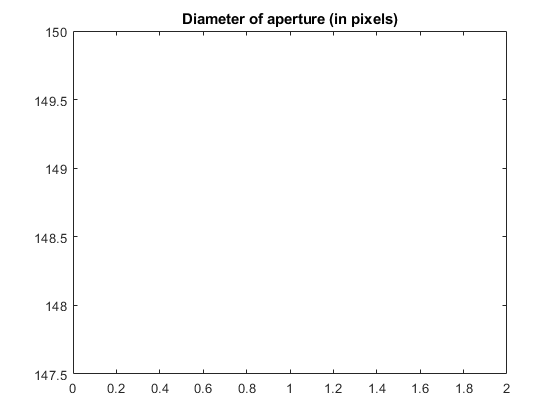


figure
plot(apertures)
title('Diameter of aperture (in pixels)')


apertures = rmoutliers(apertures,'movmedian',(finalFrame - initalFrame)*0.3);

Error using isoutlier>parseinput (line 219)
Window length argument must be a numeric or duration finite positive scalar or 2-element numeric or duration finite nonnegative vector.

Error in isoutlier (line 95)
[method, wl, dim, p, sp, vars, maxoutliers, lowup] = parseinput(a, varargin);

Error in 

plot(apertures)
title('Diameter of aperture without outliers')

% Finding peaks
peaksIx = [1:size(apertures)];
[peaks, locs, p] = findpeaks(apertures,peaksIx,'Annotate','extents');
figure
findpeaks(apertures,peaksIx,'Annotate','extents')

figure
plot(locs,peaks)
title('Diameter peaks of the apertures')

% Getting the biggest difference in the peaks
[minVal, minIx] = min(peaks);
[maxVal, maxIx] = max(peaks);
result = maxVal - minVal;

% Getting the difference on the degree of stenosis
degreeDiff = 100 - (minVal*100 / maxVal);

% Printing the results
formatStruct.Interpreter = 'tex';
formatStruct.WindowStyle = 'modal';
if degreeDiff > 50
    msgbox(sprintf('The patient has tracheobronchomalacia with a degree of stenosis of %.2f %%',degreeDiff),'Diagnosis',formatStruct)
else
    msgbox('The patient does not have tracheobronchomalacia','Diagnosis',formatStruct)
end

% \\\\\\\\\\\\\\\\\//////////////////

% cd ..\..\

function [mask, clusterRRange, clusterGRange, clusterBRange] = kmeansRGBSegmentation(frame, k, flagOuterMarks)

    % Separating the 3 different dimensions
    R = frame(:,:,1);
    G = frame(:,:,2);
    B = frame(:,:,3);
    
    % Applying kmeans
    [labels, centroids]= imsegkmeans(frame,k,"NumAttempts",3);
        
%     C = labeloverlay(frame,labels);
%     figure
%     imshow(C)
%     title("Labeled Image RGB")
    
    minR = 255; % Red channel minimum intensity 
    minG = 255; % Green channel minimum intensity 
    minB = 255; % Blue channel minimum intensity 
    maxR = 0; % Red channel maximum intensity 
    maxG = 0; % Green channel maximum intensity 
    maxB = 0; % Blue channel maximum intensity
    ix = 0; % Index of the cluster to return
    count = 0;
    for i = 1:k 
        % Mask applied to input image
        mask = labels == i;
%         cluster = frame.*uint8(mask);
%         figure
%         imshow(cluster)
%         title("RGB Cluster "+i);
        
        if flagOuterMarks == 0
            % Minimum values of ligth intensity for each channel in the cluster
            auxMinR = min(R(mask > 0));
            auxMinG = min(G(mask > 0));
            auxMinB = min(B(mask > 0));
            
            % Count the number of channels that has lower values that the current
            % lowest
            if minR > auxMinR
                count = count + 1;
            end
            if minG > auxMinG
                count = count + 1;
            end
            if minB > auxMinB
                count = count + 1;
            end
            
            % If 2 or more channels has less lighting I select it as the well
            % channel
            if count >= 2
                ix = i;
                minR = auxMinR;
                minG = auxMinG;
                minB = auxMinB;
            end
        else
            % Minimum values of ligth intensity for each channel in the cluster
            auxMaxR = max(R(mask > 0));
            auxMaxG = max(G(mask > 0));
            auxMaxB = max(B(mask > 0));
            
            % Count the number of channels that has lower values that the current
            % lowest
            if maxR < auxMaxR
                count = count + 1;
            end
            if maxG < auxMaxG
                count = count + 1;
            end
            if maxB < auxMaxB
                count = count + 1;
            end
            
            % If 2 or more channels has less lighting I select it as the well
            % channel
            if count >= 2
                ix = i;
                maxR = auxMaxR;
                maxG = auxMaxG;
                maxB = auxMaxB;
            end
        end
        
        count = 0;
    end

    % Mask of the resulting cluster
    mask = labels == ix;
    
    % Range of values on the Red spectrum
    clusterRRange = [min(R(mask > 0)) max(R(mask > 0))];
    % Range of values on the Green spectrum
    clusterGRange = [min(G(mask > 0)) max(G(mask > 0))];
    % Range of values on the Blue spectrum
    clusterBRange = [min(G(mask > 0)) max(G(mask > 0))];
    
%     B = labels .* uint8(mask);
%     C = labeloverlay(frame,B);
%     imshow(C)
%     title("Labeled Image with Additional Pixel Information")
end

function [labFrame, mask, clusterGRRange, clusterBYRange] = kmeansLabSegmentation(frame, k)
    
    % Separating the 3 different dimensions
    imLuminance = frame(:,:,1);
    ab = frame(:,:,2:3);
    ab = im2single(ab);
    a = ab(:,:,1);
    b = ab(:,:,2);
    
    % Applying kmeans only to the color dimensions
    labels = imsegkmeans(ab,k,"NumAttempts",3);
    
    B = labeloverlay(frame,labels);
%     figure
%     imshow(B)
%     title("Labeled Image a*b*")
    
    wellIx = 0; % Index of the cluster to return
    minimalLuminance = 100; % Luminance in L*a*b* goes from [0 to 100]
    for i = 1:k 
        % Mask applied to input image
        mask = labels == i;
        cluster = frame.*uint8(mask);
%         figure
%         imshow(cluster)
%         title("Cluster "+i);
        
        % Getting the luminance of the cluster
        luminance = imLuminance.*mask;
        
        % Minimum value of luminance per cluster
        maskMinLuminance = min(luminance(luminance > 0));
        
        % Storing the index of the cluster with less luminance
        if maskMinLuminance < minimalLuminance
            minimalLuminance = maskMinLuminance;
            wellIx = i;
        end
    end
    
    % Mask of the resulting cluster
    mask = labels == wellIx;
    % Range of values on the green/red spectrum
    clusterGRRange = [min(a(mask > 0)) max(a(mask > 0))];
    % Range of values on the blue/yellow spectrum
    clusterBYRange = [min(b(mask > 0)) max(b(mask > 0))];
end

function watershedSegmentation = watershedSegmentationKmeans(frame)

    [outerMostRegion, ~, ~, ~] = kmeansRGBSegmentation(frame, 2, 1);
%     figure
%     imshow(outerMostRegion)
%     title('Regional outerMostRegion')
    
    innerMostRegion= kmeansRGBSegmentation(frame, 8, 0);
%     figure
%     imshow(innerMostRegion)
%     title('Regional Minimums')

    % Regional minimas and maximas
    imGray = rgb2gray(frame);
    grayProcessed = openCloseByReconstruction(imGray);
    minimas = imregionalmin(grayProcessed);
    maximas = imregionalmax(grayProcessed);
    
    minimas = minimas & ~innerMostRegion;
    outerMostRegion = outerMostRegion | minimas | maximas;
    
    se = strel(ones(5,5));
    innerMostRegion = imclose(innerMostRegion,se);
    innerMostRegion = imerode(innerMostRegion,se);
    innerMostRegion = bwareaopen(innerMostRegion,50);
    
    outerMostRegion = imclose(outerMostRegion,se);
    outerMostRegion = imerode(outerMostRegion,se);
    outerMostRegion = bwareaopen(outerMostRegion,50);
    
%     figure
%     imshow(outerMostRegion)
%     title('Outer-Most Regions')
    
%     figure
%     imshow(innerMostRegion)
%     title('Inner-Most Regionals')
    
    D = bwdist(outerMostRegion | innerMostRegion);
    DL = watershed(D);
    bgm = DL == 0;
%     figure
%     imshow(bgm)
%     title('Watershed Ridge Lines')
    
    I2 = labeloverlay(frame,innerMostRegion | outerMostRegion);
%     figure
%     imshow(I2)
%     title('Regional Minimum and Maxima Superimposed on Frame')
    
    % Gradient of the image
    gmag = imgradient(grayProcessed);
%     figure
%     imshow(gmag,[]);
%     title('Image gradient')
    
    fgm = (innerMostRegion | outerMostRegion);
    gmag2 = imimposemin(gmag, fgm);
%     figure
%     imshow(gmag2,[])
%     title('Gradient with markers imposed')
    
    L = watershed(gmag2);
    labels = imdilate(L==0,ones(3,3)) + 2*(innerMostRegion | outerMostRegion) + 3*fgm;
    I4 = labeloverlay(frame,labels);
%     figure
%     imshow(I4)
%     title('Markers and Object Boundaries Superimposed on Frame')
    
    % labeling the watershed results
    Lrgb = label2rgb(L,'jet','w','shuffle');
%     figure
%     imshow(Lrgb)
%     title('Colored Watershed Label Matrix')
    
    % Getting the the value of the labels for the biggest minimum blob in the frame
    labelValue = L(innerMostRegion);
    % Getting the labels of the inner-most regions
    values = unique(labelValue(:,1));
    % Getting the watershed segmentation of the stenosis level
    watershedSegmentation = zeros(size(L,1), size(L,2));
    for i = 1:size(values)
        watershedSegmentation = watershedSegmentation | L == values(i);
    end
    I5 = labeloverlay(frame,watershedSegmentation);
    figure
    imshow(I5)
    title('Watershed final mask')
end


function watershedSegmentation = watershedSegmentation(preProcessedFrame, frameCropped)

    maximums = imregionalmax(preProcessedFrame);
%     figure
%     imshow(maximums)
%     title('Regional maximums')
    
    minimums = imregionalmin(preProcessedFrame);
%     figure
%     imshow(minimums)
%     title('Regional Minimums')
    
    minimum = extractClosestBlob(minimums, [size(frameCropped,1) / 2 size(frameCropped,2) / 2]);
%     figure
%     imshow(minimum)
%     title('Biggest minimum')
    
    D = bwdist(maximums | minimums);
    DL = watershed(D);
    bgm = DL == 0;
%     figure
%     imshow(bgm)
%     title('Watershed Ridge Lines')
    
    I2 = labeloverlay(frameCropped,minimums | maximums);
%     figure
%     imshow(I2)
%     title('Regional Minimum and Maxima Superimposed on Frame)
    
    se2 = strel(ones(5,5));
    fgm2 = imclose(minimums | maximums,se2);
    fgm3 = imerode(fgm2,se2);
    fgm4 = bwareaopen(fgm3,20);
    I3 = labeloverlay(frameCropped,fgm4);
%     figure
%     imshow(I3)
%     title('Modified Regional Maxima Superimposed on Frame')
    
    % Gradient of the image
    gmag = imgradient(preProcessedFrame);
%     figure
%     imshow(gmag,[]);
%     title('Image gradient')
    
    gmag2 = imimposemin(gmag, fgm4);
%     figure
%     imshow(gmag2,[])
%     title('Gradient with markers imposed')
    L = watershed(gmag2);
    labels = imdilate(L==0,ones(3,3)) + 2*(minimums | maximums) + 3*fgm4;
    I4 = labeloverlay(frameCropped,labels);
%     figure
%     imshow(I4)
%     title('Markers and Object Boundaries Superimposed on rame')
    % labeling the watershed results
    Lrgb = label2rgb(L,'jet','w','shuffle');
%     figure
%     imshow(Lrgb)
%     title('Colored Watershed Label Matrix')
    % Getting the the value of the labels for the biggest minimum blob in the frame
    labelValue = L(minimum);
    % Getting the label with maximum ocurrence
    value = mode(labelValue);
    % Getting the watershed segmentation of the stenosis level
    watershedSegmentation= L == value;
%     figure
%     imshow(watershedSegmentation);
%     title('Watershed final mask')
end

function aperture = getStenosisDegree(frameCropped, frameMask, path)
    global S frameIx previousCentroid
    %  --------- Getting the degree of aperture and saving the image -------
        % Max diff result
        edgeDetected = edge(frameMask,"canny");
        frameOutlined = imoverlay(frameCropped,edgeDetected,'yellow');
        
        firstFig = figure('visible','off');
%         firstFig = figure;
        imshow(frameOutlined);
    
        stats = regionprops(frameMask, 'Centroid', 'BoundingBox', ...
            'Orientation', 'MinFeretProperties');
        
        bbox = stats.BoundingBox;
        orientation = stats.Orientation; % Getting the perpendicular orientation
        minorAxisLen = stats.MinFeretDiameter;
        
        xCentroid = bbox(1) + bbox(3)/2;
        yCentroid = stats.Centroid(2);
        previousCentroid = [xCentroid yCentroid];
        
        % Calculating the aperture using the orientation of the blob
        % and the centroid
        sinOrient = sind(orientation);
        cosOrient = cosd(orientation);
        
        vertUpperDist = 0;
        vertLowerDist = 0;
        if orientation < 135 && orientation > -45 
            vertUpperDist = pdist([xCentroid, yCentroid; xCentroid, bbox(2), ],'euclidean');
            vertLowerDist = pdist([xCentroid, yCentroid; xCentroid, (bbox(2) + bbox(4))],'euclidean');
        else
            vertUpperDist = pdist([xCentroid, yCentroid; bbox(1), yCentroid, ],'euclidean');
            vertLowerDist = pdist([xCentroid, yCentroid; (bbox(1) + bbox(3)) ,yCentroid],'euclidean');
        end
        % Calculing the endpoints of the line of aperture from the centroid,
        % adding the relative distance to the bounding box plus a half
        xCoords(1) = xCentroid + (vertUpperDist + vertUpperDist/2) * sinOrient;
        yCoords(1) = yCentroid + (vertUpperDist + vertUpperDist/2) * cosOrient;
        xCoords(2) = xCentroid - (vertLowerDist + vertLowerDist/2) * sinOrient;
        yCoords(2) = yCentroid - (vertLowerDist + vertLowerDist/2) * cosOrient;
        
        % Distance between the two endpoints of the line
        nPoints = ceil(sqrt((xCoords(2) - xCoords(1)).^2 + (yCoords(2) - yCoords(1)).^2)) + 1;
        
        % X and Y values of the endpoints
        xvalues = round(linspace(xCoords(1), xCoords(2), nPoints));
        yvalues = round(linspace(yCoords(1), yCoords(2), nPoints));
        
        % Cropping the aperture pixels that surpass the bounding box of the blob
        if orientation < 135 && orientation > -45 
            xvalues(yvalues < bbox(2)) = [];
            yvalues(yvalues < bbox(2)) = [];
            xvalues(yvalues > (bbox(2) + bbox(4))) = [];
            yvalues(yvalues > (bbox(2) + bbox(4))) = [];
            
            yvalues(xvalues < bbox(1)) = [];
            xvalues(xvalues < bbox(1)) = [];
            yvalues(xvalues > (bbox(1) + bbox(3))) = [];
            xvalues(xvalues > (bbox(1) + bbox(3))) = [];
        else
            xvalues(yvalues < bbox(2)) = [];
            yvalues(yvalues < bbox(2)) = [];
            xvalues(yvalues > (bbox(2) + bbox(4))) = [];
            yvalues(yvalues > (bbox(2) + bbox(4))) = [];
            
            yvalues(xvalues < bbox(1)) = [];
            xvalues(xvalues < bbox(1)) = [];
            yvalues(xvalues > (bbox(1) + bbox(3))) = [];
            xvalues(xvalues > (bbox(1) + bbox(3))) = [];
        end
        
        % Mask the values of intercection of the line with the edge of the segmentation mask 
        lineMask = false(size(edgeDetected,1),size(edgeDetected,2));
        lineMask(sub2ind(size(lineMask), yvalues, xvalues)) = 1;
        
        % Dilating the line to ensure that it intersects with the edge
        lineMask = imdilate(lineMask,strel('line',5,orientation));
        lineMask = edgeDetected .* lineMask;
        
        % Values of the two farthest points of the line¡
        [row1,col1] = find(lineMask, 1, 'first');
        [row2,col2] = find(lineMask, 1, 'last');
        midpoint = ([row1 col1] + [row2 col2]).'/2;
        aperture = pdist([row1, col1; row2, col2],'euclidean');
        
        % Plot of all the data on top of the original image
        hold on;
        plot([col1,col2],[row1,row2],'c','LineWidth',2)
        plot(xCentroid, yCentroid, 'r+', 'LineWidth', 2, 'MarkerSize', 7)
        rectangle('Position',bbox,"EdgeColor",'b')
        title('Segmentation outline with the degree of stenosis');
        text(midpoint(2) + 20,midpoint(1),string(aperture),'Color',[0 1 1],'FontSize',8)
        saveas(firstFig,[pwd path S(frameIx).name]);
end

function mask = binBinarization(frame,bins)
    global previousThreshold
    [counts,binLocations] = imhist(frame,bins);
    % Getting first local maxima in the hist with a threshold of 500
    % I use this threshold to ignore small local peaks
    [pks,locs] = findpeaks(counts,'MinPeakHeight',4500);
    if not(isempty(pks)) 
        ix = locs(1) - 1; %indexing to the previous bin for the calculus
        % Setting the threshold using the % of divergence between bins
        countDiff = (counts(ix) * 100) / counts(ix + 1);
        binDiff = binLocations(ix + 1) - binLocations(ix);
        binThresh = binLocations(ix) + binDiff * ((100-countDiff)/100);
        % A 15% is substracted for fine tunning of the binarization, due to
        % oversteemation of the threshold
        binThresh = binThresh - binThresh*0.15; 
    else
        diffs = diff(counts);
        [maxDiff, diffIx] = max(diffs(diffs>=0));
        countDiff = (counts(diffIx) * 100) / counts(diffIx + 1);
        binDiff = binLocations(diffIx + 1) - binLocations(diffIx);
        binThresh = binLocations(diffIx) + binDiff * ((100-countDiff)/100);
    end
    % The previous threshold is taken into account in order to get more
    % accurate results
    if previousThreshold ~= -1
        threshDiff = binThresh - previousThreshold;
        if threshDiff >= 0
            percentageOfDiff = previousThreshold*100 / binThresh;
            binThresh = binThresh - threshDiff*(percentageOfDiff/100);
        else
            percentageOfDiff = binThresh*100 / previousThreshold;
            binThresh = binThresh + abs(threshDiff)*(percentageOfDiff/100);
        end
    end
    previousThreshold = binThresh;
    mask = frame <= binThresh;    
end

function segmentationOutline(frame, segmentation)
    edgeDetected = edge(segmentation,"canny");
    frameOutlined = imoverlay(frame,edgeDetected,'yellow');
    imshow(frameOutlined);
end

function openClosedImage = openCloseByReconstruction(frame)    
    se = strel('disk',20);
    frameOpen = imopen(frame,se);
%     figure
%     imshow(frameOpen)
%     title('Opening')
    
    frameErode = imerode(frame,se);
    frameObR = imreconstruct(frameErode,frame);
%     figure
%     imshow(frameObR)
%     title('Opening-by-Reconstruction')
    
    frameOpCl = imclose(frameOpen,se);
%     figure
%     imshow(frameOpCl)
%     title('Opening-Closing')
    
    frameObRDilated = imdilate(frameObR,se);
    frameOCRecon = imreconstruct(imcomplement(frameObRDilated),imcomplement(frameObR));
    openClosedImage = imcomplement(frameOCRecon);
%     figure
%     imshow(openClosedImage)
%     title('Opening-Closing by Reconstruction')
end

function binaryImage = extractClosestBlob(binaryImage, point)
    try
      % Get all the Centroids
      [labeledImage, numberOfBlobs] = bwlabel(binaryImage);
      blobStats = regionprops(labeledImage, 'Centroid');
      allCentroids = [blobStats.Centroid];
      allCentroids = reshape(allCentroids,2,[]).';
        
      % Get the closest Blob to the point
      [k, dist] = dsearchn(point,allCentroids);
      [~, ixStats] = min(dist);
      
      % Extract the blob using ismember().
      biggestBlob = ismember(labeledImage, ixStats);
      % Convert from integer labeled image into binary (logical) image.
      binaryImage = biggestBlob > 0;
      
    catch ME
      errorMessage = sprintf('Error in function extractClosestBlob().\n\nError Message:\n%s', ME.message);
      fprintf(1, '%s\n', errorMessage);
      uiwait(warndlg(errorMessage));
    end
end

function segmentFrame = getSegment(binFrame)
    global previousCentroid
    
    % -------- Filling holes ----------
    filledFrame = imfill(binFrame,8,'holes');
%     figure
%     imshow(filledFrame);
%     title('Binarization with filled holes');
    % ---------------------------------
    
    % ---------- Closing gaps ---------
    % With disks
    % SE = strel('disk',15,8);
    % closedFrame = imclose(filledFrame,SE);
    % imshow(closedFrame); % Circle closed
    % closedFilledFrame = imfill(closedFrame,8,'holes');
    % imshow(closedFilledFrame);
    
    % With lines
    positiveSlope = strel('line',15,45);
    negativeSlope = strel('line',15,-45);
    horizontalLine = strel('line',15,0);
    verticalLine = strel('line',15,90);
    closedFrame=imclose(filledFrame,positiveSlope);
    closedFrame=imclose(closedFrame,negativeSlope);
    closedFrame=imclose(closedFrame,horizontalLine);
    closedFrame=imclose(closedFrame,verticalLine);
    closedFilledFrame = imfill(closedFrame,8,'holes');
    
%     figure
%     imshow(closedFilledFrame);
%     title('Closed frame with gaps filled');
    
    % ---------------------------------
    
    % -- Removing small Conn. Comp. ---
    props = regionprops(closedFilledFrame, 'Area');
    allAreas = [props.Area];
    cleanedFrame = bwareaopen(closedFilledFrame, ceil(max(allAreas)*0.5));
    
    props = regionprops(cleanedFrame, 'Centroid', 'BoundingBox');
    CC = bwconncomp(cleanedFrame);
    L = labelmatrix(CC);
    % If there are more than on blob, I get the closest to the centroid of
    % the last frame with a valid centroid
    ixProps = 1; % Index of the stats struct
    centroid = [];
    if numel(props) > 1
        centroids = [props.Centroid];
        centroids = reshape(centroids,2,[]).';
        [k, dist] = dsearchn(previousCentroid,centroids);
        [~, ixProps] = min(dist);
        centroid = props(ixProps).Centroid;
    else
        centroid = props.Centroid;
    end
    
    cleanedFrame = L == ixProps;
    
%     imshow(cleanedFrame);
%     title('Removal of unnecessary connected components and filling gaps');
%     figure
%     
    positiveSlope = strel('line',25,45);
    negativeSlope = strel('line',25,-45);
    horizontal = strel('line',25,0);
    vertical = strel('line',25,90);
    closeBlobFrame=imclose(cleanedFrame,positiveSlope);
    closeBlobFrame=imclose(closeBlobFrame,negativeSlope);
    closeBlobFrame=imclose(closeBlobFrame,horizontal);
    closeBlobFrame=imclose(closeBlobFrame,vertical);
    closeBlobFrame = imfill(closeBlobFrame,8,'holes');
    
%     imshow(closeBlobFrame);
%     title('Final segmentation mask');
%     figure

    segmentFrame = closeBlobFrame;
    % ---------------------------------
    % ---------------------------------
end